# Load data

function [Eps_data, Mu0_data, mu_out_data, dmode_data, flag_values] = load_samples(filename_pattern, l2_thr)
    file_list = dir(filename_pattern);
    
    NUM_FILES = length(file_list);

    bar = waitbar(0, sprintf('Loading %d files...\n', NUM_FILES), 'Name', 'Process Monitor');
    
    % Preallocate arrays to maximum possible size for speed
    Eps_data    = zeros(NUM_FILES, 1);
    Mu0_data    = zeros(NUM_FILES, 1);
    mu_out_data = zeros(NUM_FILES, 1);
    dmode_data  = zeros(NUM_FILES, 1);
    flag_values = zeros(NUM_FILES, 1, 'int8'); 
    
    for k = 1:NUM_FILES
        current_file = file_list(k).name;
        data = load(current_file);
        ep = data.ep;      Eps_data(k) = ep;
        mu0 = data.mu0;    Mu0_data(k) = mu0;

        l2_hist = data.L2_HIST(:);
        dmode_hist = data.DMODE_HIST;

        t_grid = data.dt * (0:length(l2_hist)-1)';
        mu_grid = t_grid * ep + mu0;
    
        % Find where L2 threshold is reached
        j_l2_thr = find(l2_hist > l2_thr & mu_grid > 0, 1);
        if isempty(j_l2_thr)
            fprintf('File %s at index %d never reaches the l2 threshold.\n', current_file, k)
    
            [max_val, max_idx] = max(l2_hist);
            fprintf('Max L2 is %.3f, which occurs at mu = %.5f\n', max_val, mu_grid(max_idx));
            
            mu_out_data(k) = -1;
            dmode_data(k)  = -1;
            flag_values(k) = true;
            continue;
        end
    
        t_l2_thr       = t_grid(j_l2_thr);
        mu_out_data(k) = mu_grid(j_l2_thr);
    
        % Find dominate mode at high amplitude
        j_dom_mode_at_thr = find(dmode_hist(:, 1) < t_l2_thr, 1, 'last');
        if isempty(j_dom_mode_at_thr)
            j_dom_mode_at_thr = 1; 
        end
        dmode_data(k) = int32(dmode_hist(j_dom_mode_at_thr, 2) * data.Lx / pi);  
        
        if data.datatype == "Float64"
            threshold = 1e-25;
        elseif data.datatype == "Float64x4"
            threshold = 1e-50;
        end

        amplitudes_very_low = any(data.AMP_HISTS < threshold, 'all');
        
        % Detect how many digits are needed to resolve a1
        a1 = data.AMP_HISTS(1, :);
        num_digits = 2*max(-log10(a1));

        if data.datatype == "Float64"
            a1_resolvable = num_digits <= 16;
        elseif data.datatype == "Float64x4"
            a1_resolvable = num_digits <= 34;
        end

        if amplitudes_very_low
            fprintf('Amplitudes reach low values for ep=1e%.4f, mu0=%.2f\n', log10(ep), mu0);
            flag_values(k) = 1;
        elseif ~a1_resolvable
            fprintf('Need %.2f digits for ep=1e%.4f, mu0=%.2f\n', num_digits, log10(ep), mu0);
            flag_values(k) = 2;
        end

          
        clear data t_grid mu_grid l2_hist dmode_hist

        % Update progress bar
        currentProgress = k / NUM_FILES;
        statusText = sprintf('Processing file %d of %d...', k, NUM_FILES);
        waitbar(currentProgress, bar, statusText);
    end
    delete(bar);
end

Need 17.98 digits for ep=1e-2.0808, mu0=-0.30
Need 16.85 digits for ep=1e-2.1212, mu0=-0.23
Need 16.18 digits for ep=1e-2.1212, mu0=-0.26
Need 16.07 digits for ep=1e-2.2020, mu0=-0.12
Need 17.56 digits for ep=1e-2.2020, mu0=-0.16
Need 16.72 digits for ep=1e-2.2020, mu0=-0.17
Need 16.51 digits for ep=1e-2.2424, mu0=-0.02
Need 16.38 digits for ep=1e-2.2424, mu0=-0.11
Need 17.38 digits for ep=1e-2.2424, mu0=0.00
Need 16.38 digits for ep=1e-3.3737, mu0=-0.16
Need 16.59 digits for ep=1e-3.3737, mu0=-0.41
Need 16.01 digits for ep=1e-3.4141, mu0=-0.29
Need 18.51 digits for ep=1e-3.4545, mu0=-0.42
Need 16.14 digits for ep=1e-3.4949, mu0=-0.07
Need 16.62 digits for ep=1e-3.4949, mu0=-0.28
Need 17.25 digits for ep=1e-3.5758, mu0=-0.23
Need 16.42 digits for ep=1e-3.5758, mu0=-0.23
Need 16.03 digits for ep=1e-3.6162, mu0=-0.24
Amplitudes reach low values for ep=1e-3.6162, mu0=-0.50
Amplitudes reach low values for ep=1e-3.6566, mu0=-0.48
Amplitudes reach low values for ep=1e-3.6566, mu0=-0.48
Ampli

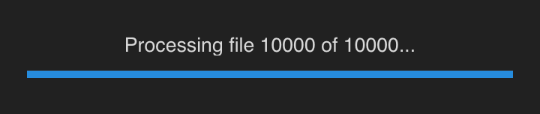

L_thr = 1e0;
[Eps_data, Mu0_data, mu_out_data, dmode_data, flag_values] = load_samples('sample*Float64.mat', L_thr);

[Eps_data_64x4, Mu0_data_64x4, ~, dmode_data_64x4, flag_values_64x4] = load_samples('sample*Float64x4.mat', L_thr);

Amplitudes reach low values for ep=1e-4.1452, mu0=-0.47
Amplitudes reach low values for ep=1e-4.1452, mu0=-0.50
Amplitudes reach low values for ep=1e-4.2258, mu0=-0.45
Amplitudes reach low values for ep=1e-4.2258, mu0=-0.47
Amplitudes reach low values for ep=1e-4.2258, mu0=-0.50
Amplitudes reach low values for ep=1e-4.3065, mu0=-0.40
Amplitudes reach low values for ep=1e-4.3065, mu0=-0.42
Amplitudes reach low values for ep=1e-4.3065, mu0=-0.45
Amplitudes reach low values for ep=1e-4.3065, mu0=-0.47
Amplitudes reach low values for ep=1e-4.3065, mu0=-0.50
Amplitudes reach low values for ep=1e-4.3871, mu0=-0.38
Amplitudes reach low values for ep=1e-4.3871, mu0=-0.40
Amplitudes reach low values for ep=1e-4.3871, mu0=-0.42
Amplitudes reach low values for ep=1e-4.3871, mu0=-0.45
Amplitudes reach low values for ep=1e-4.3871, mu0=-0.47
Amplitudes reach low values for ep=1e-4.3871, mu0=-0.50
Amplitudes reach low values for ep=1e-4.4677, mu0=-0.35
Amplitudes reach low values for ep=1e-4.4677, mu

[Eps_data_val, Mu0_data_val, ~, dmode_data_val, ~] = load_samples('val_sample*Float64.mat', L_thr);

Amplitudes reach low values for ep=1e-3.7000, mu0=-0.50


## Predict the high amplitude onset time and resulting mode

% --- PARAMETERS ---
delta = 2^(-10); 
amp_thr =  L_thr/sqrt(20 * pi) * sqrt(0.5); % sqrt(0.5) prefactor for better domain 

% --- FUNCTIONS ---
ktilde2 = @(k) (k / 10)^2; 

% Use element-wise operations (.*, ./, .^) for grid evaluation
Lambdak = @(mu, k) (mu.^2 .* ktilde2(k) / 2 - mu .* ktilde2(k)^2);

% Onset surface equations
muk_hom_onset =  @(eps, mu0, k) ktilde2(k) + sqrt(ktilde2(k)^2 + 2 / ktilde2(k) .* ...
    (-eps .* log(abs(delta)) + eps .* log(amp_thr) + Lambdak(mu0, k)));

mu1_onset = @(eps, mu0) muk_hom_onset(eps, mu0, 1);
mu2_onset = @(eps, mu0) muk_hom_onset(eps, mu0, 2);
mu3_hom_onset = @(eps, mu0) muk_hom_onset(eps, mu0, 3);
mu4_hom_onset = @(eps, mu0) muk_hom_onset(eps, mu0, 4);
mu5_hom_onset = @(eps, mu0) muk_hom_onset(eps, mu0, 5);

% Particular solutions

a3 = (ktilde2(3) - 3 * ktilde2(1)) / 2;
b3 = 3 * ktilde2(1)^2 - ktilde2(3)^2;
sigma3 = @(eps) sqrt(eps ./ a3);
mean3 = -b3 / (2 * a3); 

a4 = (ktilde2(4) - 2 * ktilde2(1) - ktilde2(2)) / 2;
b4 = 2*ktilde2(1)^2 + ktilde2(2)^2 - ktilde2(4)^2;
sigma4 = @(eps) sqrt(eps ./ a4);
mean4 = -b4 / (2 * a4); 

a5 = (ktilde2(5) - 2 * ktilde2(1) - ktilde2(3)) / 2;
b5 = 2*ktilde2(1)^2 + ktilde2(3)^2 - ktilde2(5)^2;
sigma5 = @(eps) sqrt(eps ./ a5);
mean5 = -b5 / (2 * a5); 


% k=3 Resonance
C3 = @(eps, mu0) sqrt(pi ./ (4 * a3 .* eps)) .* ktilde2(3).* delta.^3 .* ...
    exp(- 3 * Lambdak(mu0, 1) ./ eps + b3^2 ./ (4 * a3 .* eps)); 
logC3 = @(eps, mu0) 0.5 * log(pi / (4 * a3)) - 0.5 * log(eps) + log(ktilde2(3)) + 3 * log(delta) ...
    - 3 * Lambdak(mu0, 1) ./ eps + b3^2 ./ (4 * a3 .* eps); 

mu3_res_onset = @(eps, mu0) ktilde2(3) + sqrt(ktilde2(3)^2 + 2 / ktilde2(3) .* ...
         (eps .* log(amp_thr) - eps .* log(C3(eps, mu0) .* erfc((mu0 - mean3) ./ sigma3(eps)))));
u3_res = @(mu, mu0, eps) C3(eps, mu0) .* exp(Lambdak(mu, 3) ./ eps) .* ...
    (erf((mu - mean3) ./ sigma3(eps)) - erf((mu0 - mean3) ./ sigma3(eps)));
log_u3_res = @(mu, mu0, eps) logC3(eps, mu0) + Lambdak(mu, 3) ./ eps + ...
    log_abs_erf_diff((mu - mean3) ./ sigma3(eps), (mu0 - mean3) ./ sigma3(eps));

% k=4 Resonance
C4 = @(eps, mu0) 3 * sqrt(pi ./ (4 * a4 .* eps)) .* ktilde2(4) .* delta.^3 .* ...
    exp(- 2 * Lambdak(mu0, 1) ./ eps - Lambdak(mu0, 2) ./ eps + b4^2 ./ (4 * a4 .* eps));
logC4 = @(eps, mu0) log(3) + 0.5 * log(pi / (4 * a4)) - 0.5 * log(eps) + log(ktilde2(4)) + 3 * log(delta) + ...
    - 2 * Lambdak(mu0, 1) ./ eps - Lambdak(mu0, 2) ./ eps + b4^2 ./ (4 * a4 .* eps);

mu4_res_onset = @(eps, mu0) ktilde2(4) + sqrt(ktilde2(4)^2 + 2 / ktilde2(4) .* ...
    (eps .* log(amp_thr) - eps .* log(C4(eps, mu0) .* erfc((mu0 - mean4) ./ sigma4(eps)))));

u4_res = @(mu, mu0, eps) C4(eps, mu0) .* exp(Lambdak(mu, 4) ./ eps) .* ...
    (erf((mu - mean4) ./ sigma4(eps)) - erf((mu0 - mean4) ./ sigma4(eps)));
log_u4_res = @(mu, mu0, eps) logC4(eps, mu0) + Lambdak(mu, 4) ./ eps + ...
    log_abs_erf_diff((mu - mean4) ./ sigma4(eps), (mu0 - mean4) ./ sigma4(eps));

% k=5 Resonance (1, 2, 2)
C5 = @(eps, mu0) 3 * sqrt(pi ./ (4 * a5 .* eps)) .* ktilde2(5) .* delta.^3 .* ...
    exp(- 2 * Lambdak(mu0, 2) ./ eps - Lambdak(mu0, 1) ./ eps + b5^2 ./ (4 * a5 .* eps));
logC5 = @(eps, mu0) log(3) + 0.5 * log(pi / (4 * a5)) - 0.5 * log(eps) + log(ktilde2(5)) + 3 * log(delta) + ...
    - 2 * Lambdak(mu0, 2) ./ eps - Lambdak(mu0, 1) ./ eps + b5^2 ./ (4 * a5 .* eps);

mu5_res_onset = @(eps, mu0) ktilde2(5) + sqrt(ktilde2(5)^2 + 2 / ktilde2(5) .* ...
    (eps .* log(amp_thr) - eps .* log(C5(eps, mu0) .* erfc((mu0 - mean5) ./ sigma5(eps)))));

u5_res = @(mu, mu0, eps) C5(eps, mu0) .* exp(Lambdak(mu, 5) ./ eps) .* ...
    (erf((mu - mean5) ./ sigma5(eps)) - erf((mu0 - mean5) ./ sigma5(eps)));
log_u5_res = @(mu, mu0, eps) logC5(eps, mu0) + Lambdak(mu, 5) ./ eps + ...
    log_abs_erf_diff((mu - mean5) ./ sigma5(eps), (mu0 - mean5) ./ sigma5(eps));


% --- GRID SETUP ---
% Create a dense grid over the specified domain

eps_coarse = unique(Eps_data(:));
mu0_coarse = unique(Mu0_data(:));

% 2. Define refinement factor
refine_factor = 10; 

% 3. Directly calculate new dense grid sizes
N_eps_dense = (length(eps_coarse) - 1) * refine_factor + 1;
N_mu0_dense = (length(mu0_coarse) - 1) * refine_factor + 1;

% 4. Generate the dense vector limits
eps_vec = logspace(log10(min(eps_coarse)), log10(max(eps_coarse)), N_eps_dense);
mu0_vec = linspace(min(mu0_coarse), max(mu0_coarse), N_mu0_dense);

[Eps, Mu0] = meshgrid(eps_vec, mu0_vec);

% Evaluate homogenous surfaces
M1    = evaluate_real(mu1_onset, Eps, Mu0);
M2    = evaluate_real(mu2_onset, Eps, Mu0);
M3_h  = evaluate_real(mu3_hom_onset, Eps, Mu0);
M3_r_approx  = evaluate_real(mu3_res_onset, Eps, Mu0);
M4_h = evaluate_real(mu4_hom_onset, Eps, Mu0);
M4_r_approx = evaluate_real(mu4_res_onset, Eps, Mu0);
M5_h = evaluate_real(mu5_hom_onset, Eps, Mu0);
M5_r_approx = evaluate_real(mu5_res_onset, Eps, Mu0);

M3_valid_region = (M3_r_approx - mean3) ./ sigma3(Eps) > 1 & ~isinf(M3_r_approx);
M4_valid_region = (M4_r_approx - mean4) ./ sigma4(Eps) > 1 & ~isinf(M4_r_approx);
M5_valid_region = (M5_r_approx - mean5) ./ sigma5(Eps) > 1 & ~isinf(M5_r_approx);

M3_r_approx(~M3_valid_region) = NaN;
M4_r_approx(~M4_valid_region) = NaN;
M5_r_approx(~M5_valid_region) = NaN;

% Stack surfaces and find the minimum value and its corresponding index (mode)
AllSurfaces = cat(3, M1, M2, M3_h, M3_r_approx, M4_h, M4_r_approx, M5_h, M5_r_approx);
[MU_approx, MinIdx_approx] = min(AllSurfaces, [], 3, 'omitnan');

## Compute \mu^pred and j^pred numerically

% technically not .... add def
% --- Evaluate resonance surfaces ---
% Flatten the 1000x1000 meshes into 1D vectors (1,000,000 elements)
flat_Eps = Eps(:);
flat_Mu0 = Mu0(:);
N_points = length(flat_Eps);

% Initial Guess for M3_r
mu_guess3 = M3_r_approx;
nan_mask3 = isnan(M3_r_approx);
mu_guess3(nan_mask3) = MU_approx(nan_mask3);
flat_mu_guess3 = mu_guess3(:);

% Initial Guess for M4_r
mu_guess4 = M4_r_approx;
nan_mask4 = isnan(M4_r_approx);
mu_guess4(nan_mask4) = MU_approx(nan_mask4);
flat_mu_guess4 = mu_guess4(:);

% Initial Guess for M5_r
mu_guess5 = M5_r_approx;
nan_mask5 = isnan(M5_r_approx);
mu_guess5(nan_mask5) = MU_approx(nan_mask5);
flat_mu_guess5 = mu_guess5(:);

fprintf('Solving M3_r surface...\n');

Solving M3_r surface...


flat_M3_r = arrayfun(@(mu_in, eps, mu_out_guess) fzero(...
    @(mu) log_u3_res(mu, mu_in, eps) - log(amp_thr), ...
    mu_out_guess), ...
    flat_Mu0, flat_Eps, flat_mu_guess3);
M3_r = reshape(flat_M3_r, size(Eps));

fprintf('Solving M4_r surface...\n');

Solving M4_r surface...


flat_M4_r = arrayfun(@(mu_in, eps, mu_out_guess) fzero(...
    @(mu) log_u4_res(mu, mu_in, eps) - log(amp_thr), ...
    mu_out_guess), ...
    flat_Mu0, flat_Eps, flat_mu_guess4);
M4_r = reshape(flat_M4_r, size(Eps));

fprintf('Solving M5_r surface...\n');

Solving M5_r surface...


flat_M5_r = arrayfun(@(mu_in, eps, mu_out_guess) fzero(...
    @(mu) log_u5_res(mu, mu_in, eps) - log(amp_thr), ...
    mu_out_guess), ...
    flat_Mu0, flat_Eps, flat_mu_guess5);
M5_r = reshape(flat_M5_r, size(Eps));

% Stack surfaces and find the minimum value and its corresponding index (mode)
AllSurfacesNumerical = cat(3, M1, M2, M3_h, M3_r, M4_h, M4_r, M5_h, M5_r);
[MU_pred, MinIdx_pred] = min(AllSurfacesNumerical, [], 3, 'omitnan');

## $\mu^{approx}$ plot

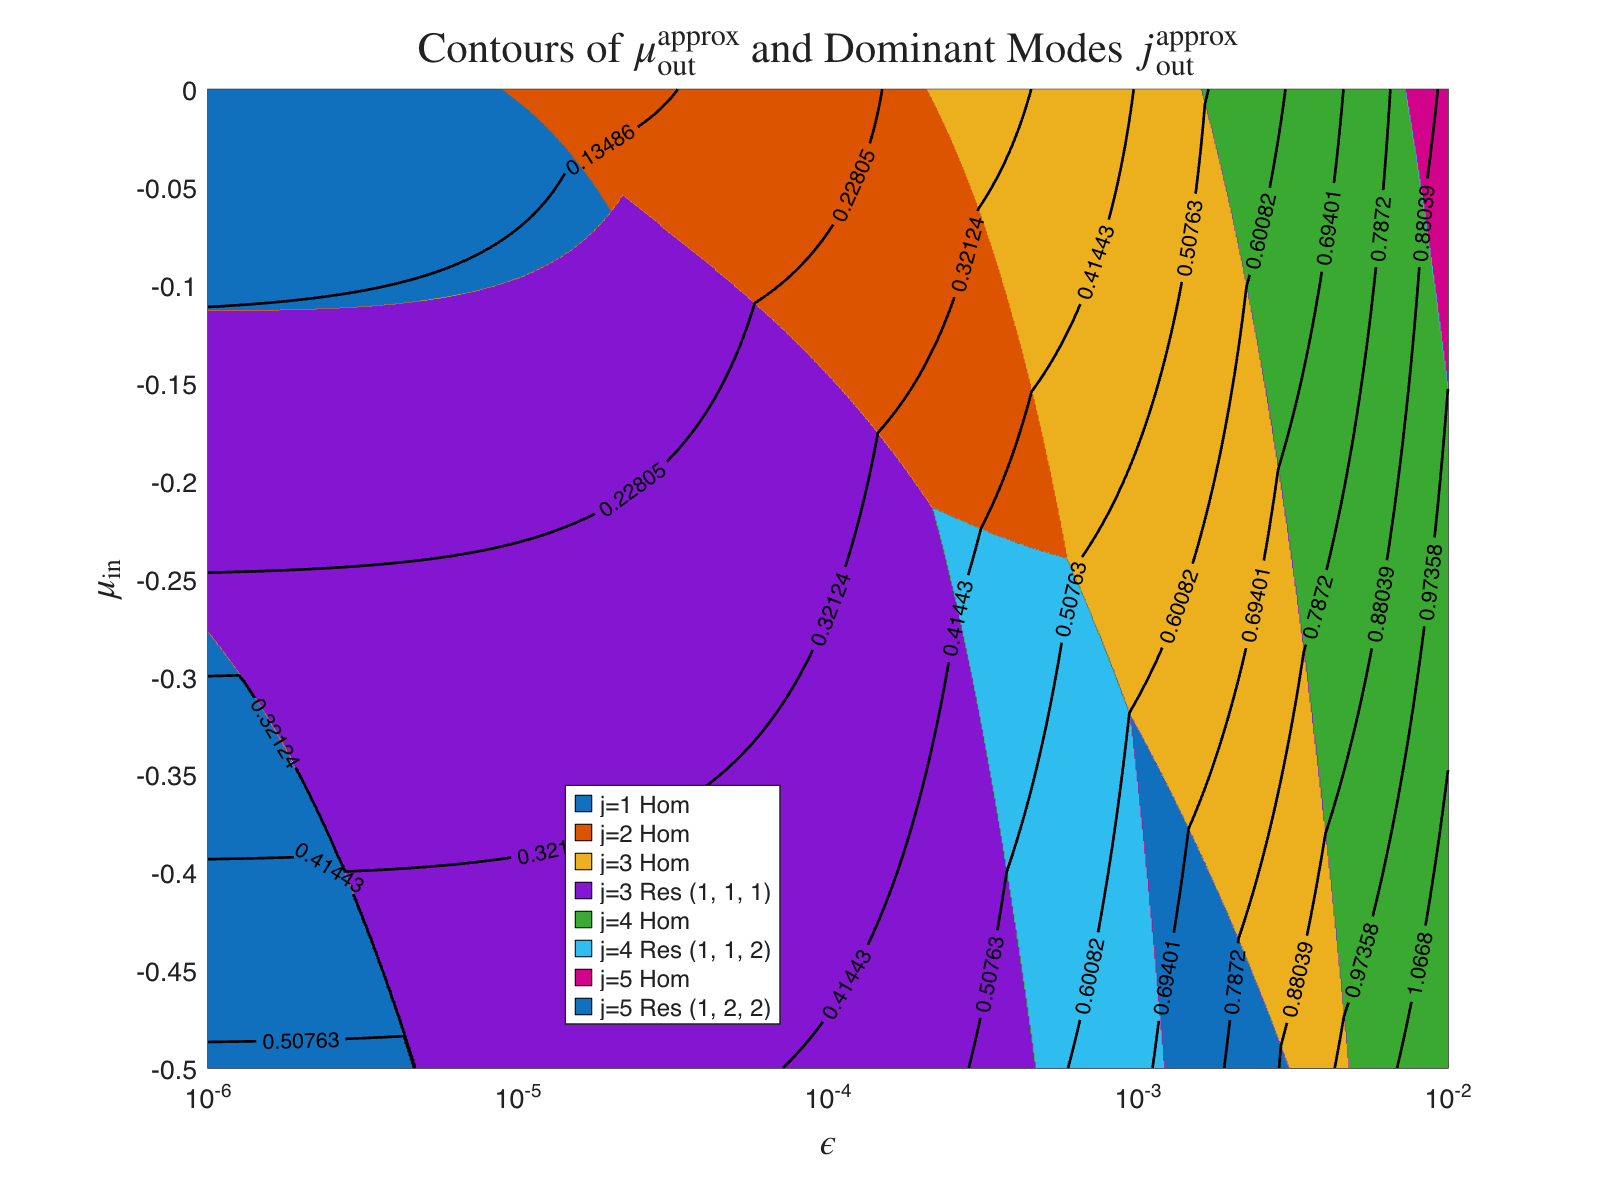

figure('Position', [200 200 800 600], 'Resize', false);
hold on;

% Plot the regions identifying which mode is the minimum
[~, h_reg] = contourf(Eps, Mu0, MinIdx_approx, [1 2 3 4 5 6 7 8], 'LineStyle', 'none');

% Plot the contour lines of the minimum surface itself
[C_lines, h_lines] = contour(Eps, Mu0, MU_approx, 11, 'k', 'LineWidth', 1);
clabel(C_lines, h_lines, 'FontSize', 8, 'Color', 'k'); % Add labels to the contour lines

max_mapped_color = max(MinIdx_approx, [],  'all'); 
clim([1, max_mapped_color]); 
colors = colormap(lines(max_mapped_color));

% Formatting
set(gca, 'XScale', 'log');
xlim([1e-6, 1e-2]);
ylim([-0.5, 0]);

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_\mathrm{in}$', 'Interpreter', 'latex', 'FontSize', 14);
title("Contours of $\mu_{\mathrm{out}}^{\mathrm{approx}}$ and Dominant Modes $j^{\mathrm{approx}}_{\mathrm{out}}$", ...
      'Interpreter', 'latex', 'FontSize', 16);

% Custom Legend for the regions
p = gobjects(1, length(max_mapped_color));
for i = 1:max_mapped_color
    p(i) = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
end

legend(p, {'j=1 Hom', 'j=2 Hom', 'j=3 Hom', 'j=3 Res (1, 1, 1)', 'j=4 Hom', 'j=4 Res (1, 1, 2)', 'j=5 Hom', 'j=5 Res (1, 2, 2)'}, ...
    'Location', 'best', 'Interpreter', 'tex');

grid on;
box on;
hold off;

## Make a contour plot of the minimum surface for the when each

approximation hits L'_thr

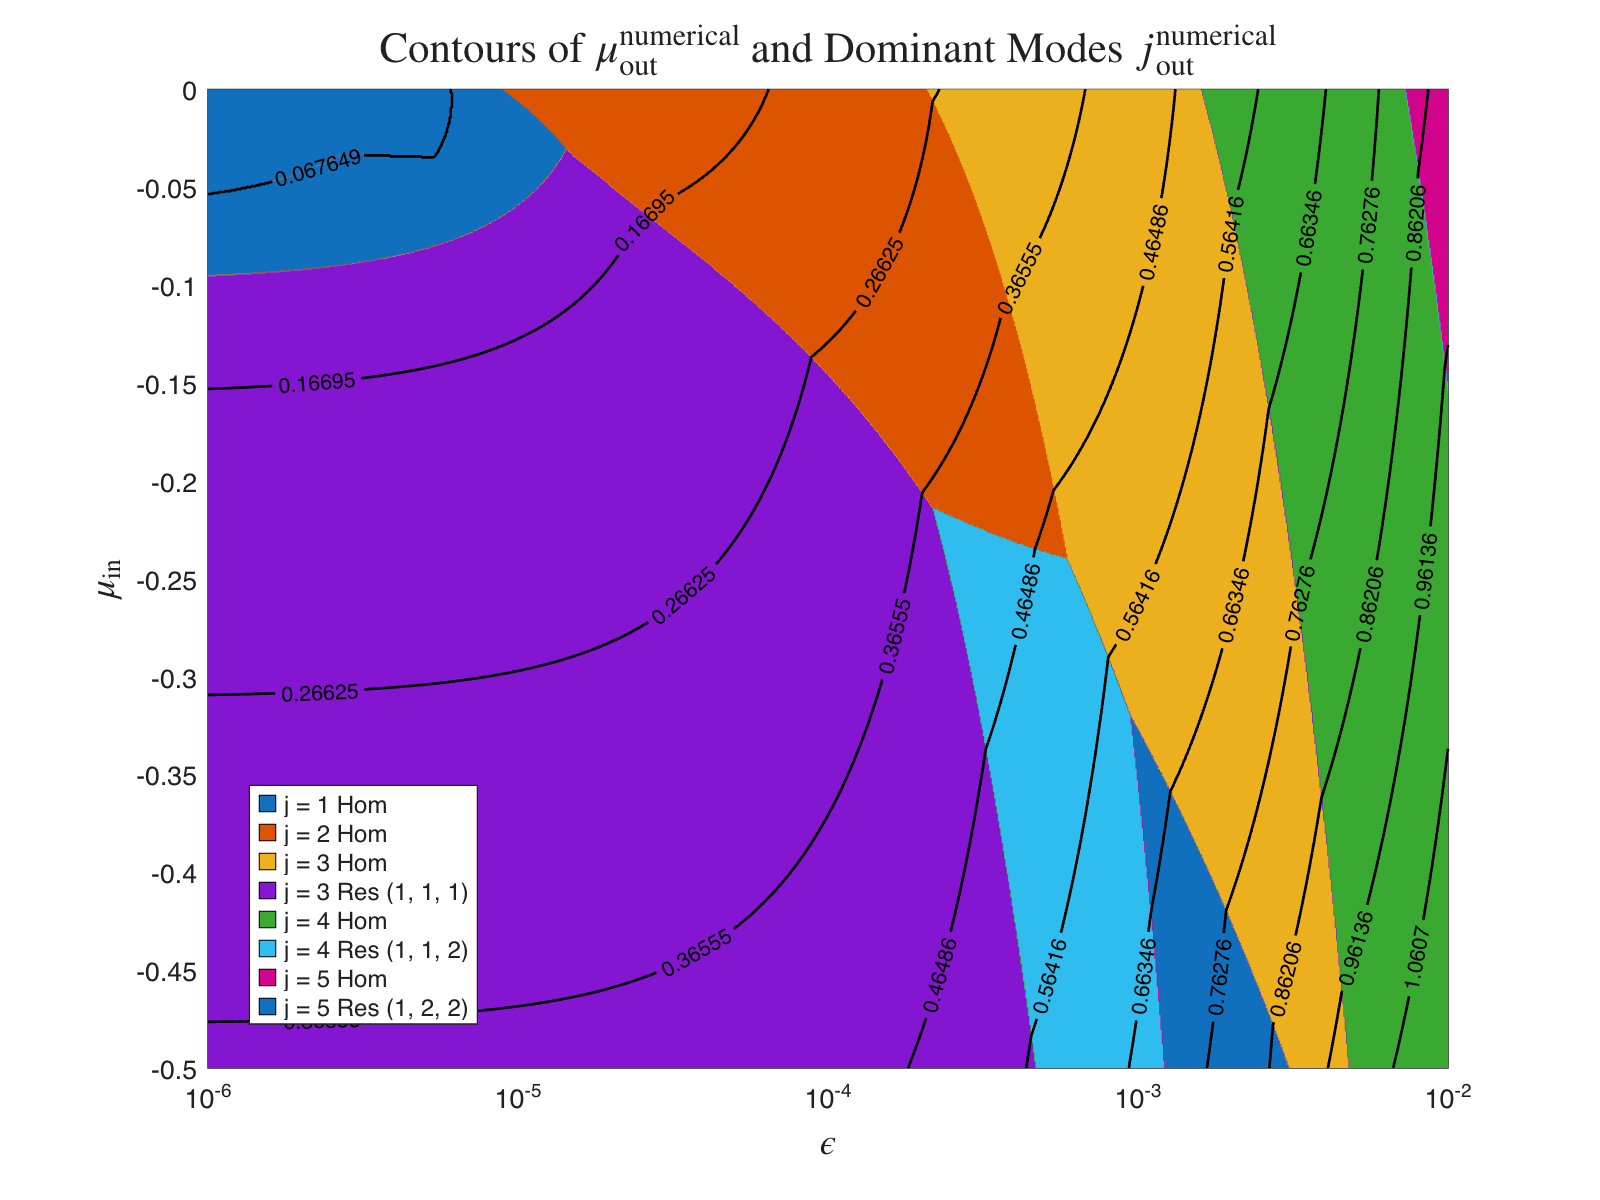

figure('Position', [200 200 800 600], 'Resize', false);
hold on;

% Plot the regions identifying which mode is the minimum
[~, h_reg] = contourf(Eps, Mu0, MinIdx_pred, [1 2 3 4 5 6 7 8], 'LineStyle', 'none');

% Plot the contour lines of the minimum surface itself
[C_lines, h_lines] = contour(Eps, Mu0, MU_pred, 11, 'k', 'LineWidth', 1);
clabel(C_lines, h_lines, 'FontSize', 8, 'Color', 'k'); % Add labels to the contour lines

max_mapped_color = max(MinIdx_pred, [],  'all'); 
clim([1, max_mapped_color]); 
colors = colormap(lines(max_mapped_color));

% Formatting
set(gca, 'XScale', 'log');
xlim([1e-6, 1e-2]);
ylim([-0.5, 0]);

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_\mathrm{in}$', 'Interpreter', 'latex', 'FontSize', 14);
title("Contours of $\mu_{\mathrm{out}}^{\mathrm{numerical}}$ and Dominant Modes $j^{\mathrm{numerical}}_{\mathrm{out}}$", ...
    'Interpreter', 'latex', 'FontSize', 16);

% Custom Legend for the regions
p = gobjects(1, length(max_mapped_color));
for i = 1:max_mapped_color
    p(i) = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
end

legend(p, {'j = 1 Hom', 'j = 2 Hom', 'j = 3 Hom', 'j = 3 Res (1, 1, 1)', 'j = 4 Hom', 'j = 4 Res (1, 1, 2)',...
    'j = 5 Hom', 'j = 5 Res (1, 2, 2)'}, 'Location', 'best', 'Interpreter', 'tex');

grid on;
box on;
hold off;

## Plot real data

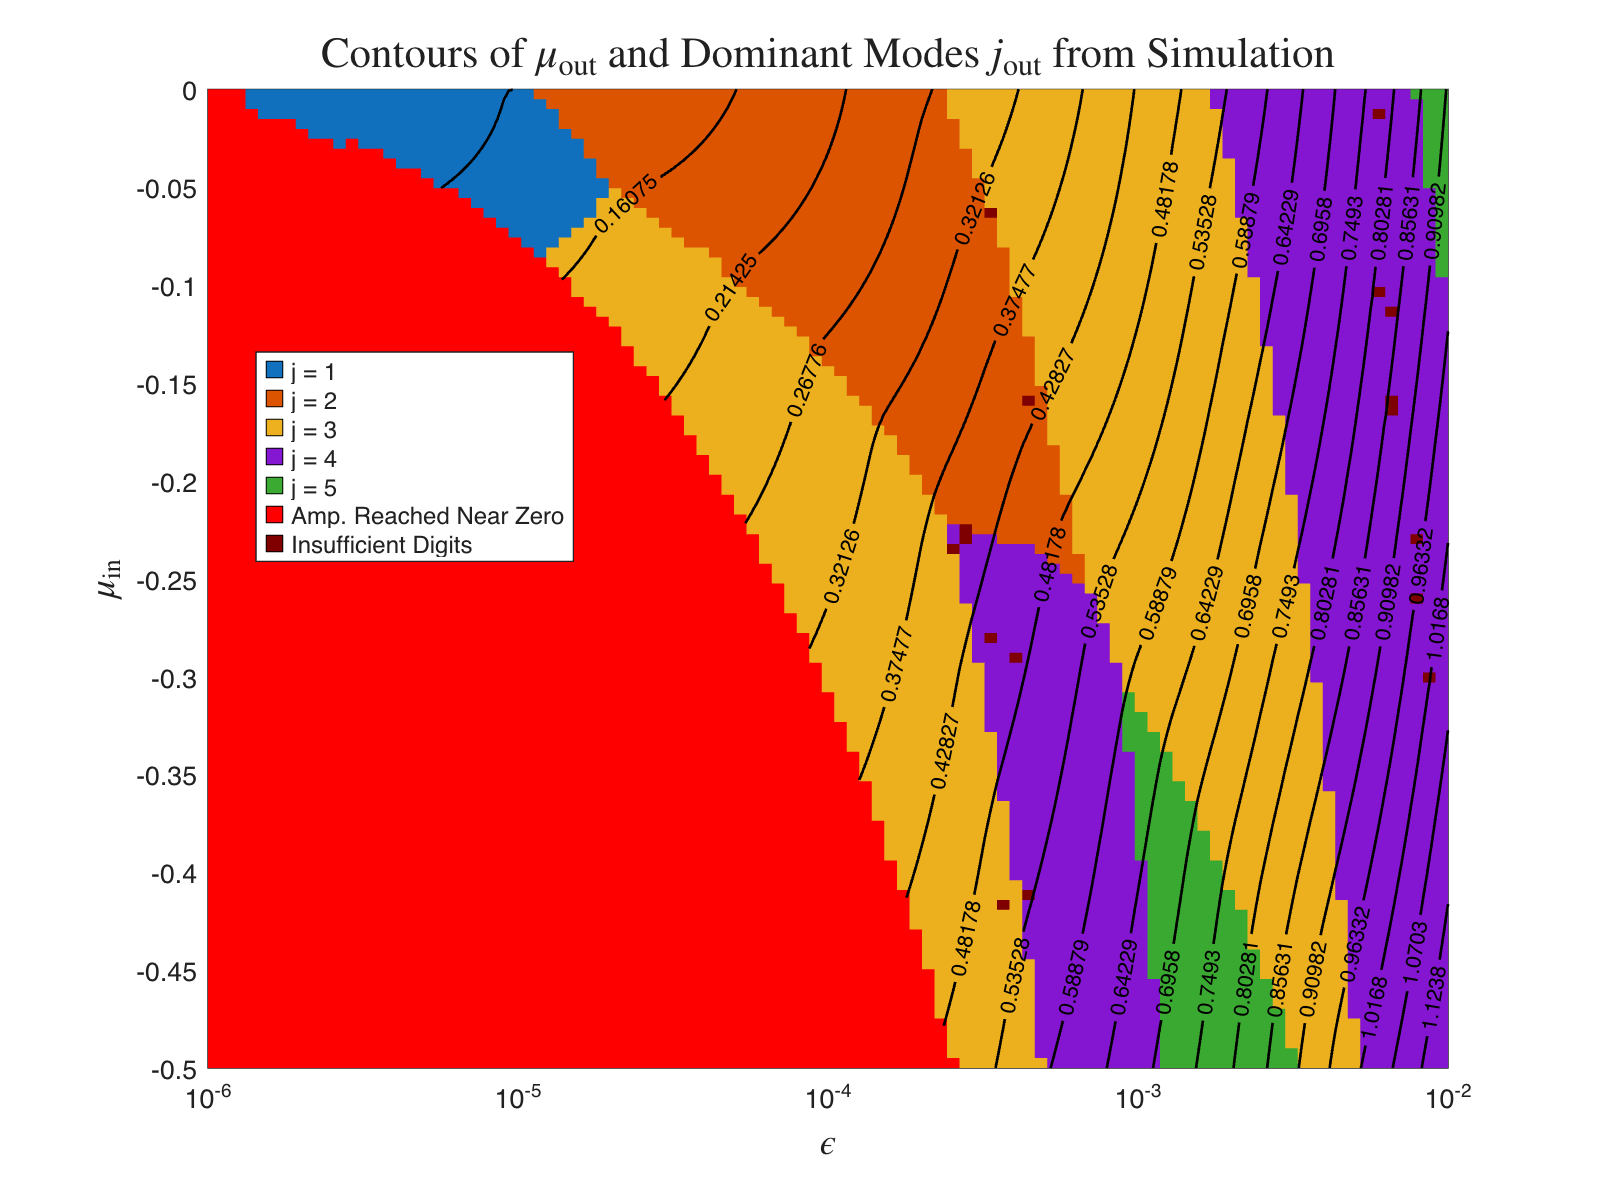

modified_mode_data = dmode_data;

% Define special identifiers for flags above the highest physical mode
max_physical_mode = max(dmode_data); 
val_flag1 = max_physical_mode + 1; % Value representing Flag 1
val_flag2 = max_physical_mode + 2; % Value representing Flag 2

% Overwrite mode values where flags are triggered
modified_mode_data(flag_values == 1) = val_flag1;
modified_mode_data(flag_values == 2) = val_flag2;

Eps_vec = unique(Eps_data);
Mu0_vec = unique(Mu0_data);
[Eps_grid, Mu0_grid] = meshgrid(Eps_vec, Mu0_vec);


% Interpolate onto the full grid (preserves integer modes with 'nearest')
C_grid = griddata(Eps_data, Mu0_data, modified_mode_data, Eps_grid, Mu0_grid, 'nearest');
MuOut_grid = griddata(Eps_data(flag_values == 0), Mu0_data(flag_values == 0), mu_out_data(flag_values == 0), Eps_grid, Mu0_grid, 'linear');


% Create the solid color grid plot
figure('Position', [200 200 800 600], 'Resize', false);
h = pcolor(Eps_grid, Mu0_grid, C_grid); 
hold on;
shading flat; 
set(gca, 'XScale', 'log');

% Plot 20 contour lines of the onset surface
[C_lines_mu, h_lines_mu] = contour(Eps_grid, Mu0_grid, MuOut_grid, 20, 'k', 'LineWidth', 1);
clabel(C_lines_mu, h_lines_mu, 'FontSize', 8, 'Color', 'k');

% Colors
base_colors = lines(max_physical_mode);
custom_colormap = [base_colors; ...
    1.0, 0.0, 0.0;   % Color for Flag 1 (Red)
    0.5, 0.0, 0.0];  % Color for Flag 2 (Dark Red)

colormap(custom_colormap);
clim([1, max_physical_mode + 2]);

% Formatting
set(gca, 'XScale', 'log');
xlim([1e-6, 1e-2]);
ylim([-0.5, 0]);

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_\mathrm{in}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Simulated Contours of $\mu_{out}$ and Dominant Modes', 'Interpreter', 'latex', 'FontSize', 16);
title("Contours of $\mu_{\mathrm{out}}$ and Dominant Modes $j_{\mathrm{out}}$ from Simulation", ...
    'Interpreter', 'latex', 'FontSize', 16);

% Custom Legend for the regions
total_legend_items = max_physical_mode + 2;
p = gobjects(1, total_legend_items);
for i = 1:max_physical_mode
    p(i) = plot(NaN, NaN, 's', 'DisplayName', sprintf('j = %d', i), 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
end

% Add Flag 1 (Red) to legend
p(max_physical_mode + 1) = plot(NaN, NaN, 's', 'DisplayName', 'Amp. Reached Near Zero', ...
    'MarkerFaceColor', custom_colormap(val_flag1, :), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);


% Add Flag 2 (Dark Red) to legend
p(max_physical_mode + 2) = plot(NaN, NaN, 's', 'DisplayName', 'Insufficient Digits', ...
    'MarkerFaceColor', custom_colormap(val_flag2, :), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);

legend(p, 'Location', 'best', 'Interpreter', 'tex');
hold off;
grid on;
box on;

## Plot Float64x4 vs Float64

## Mask flagged data

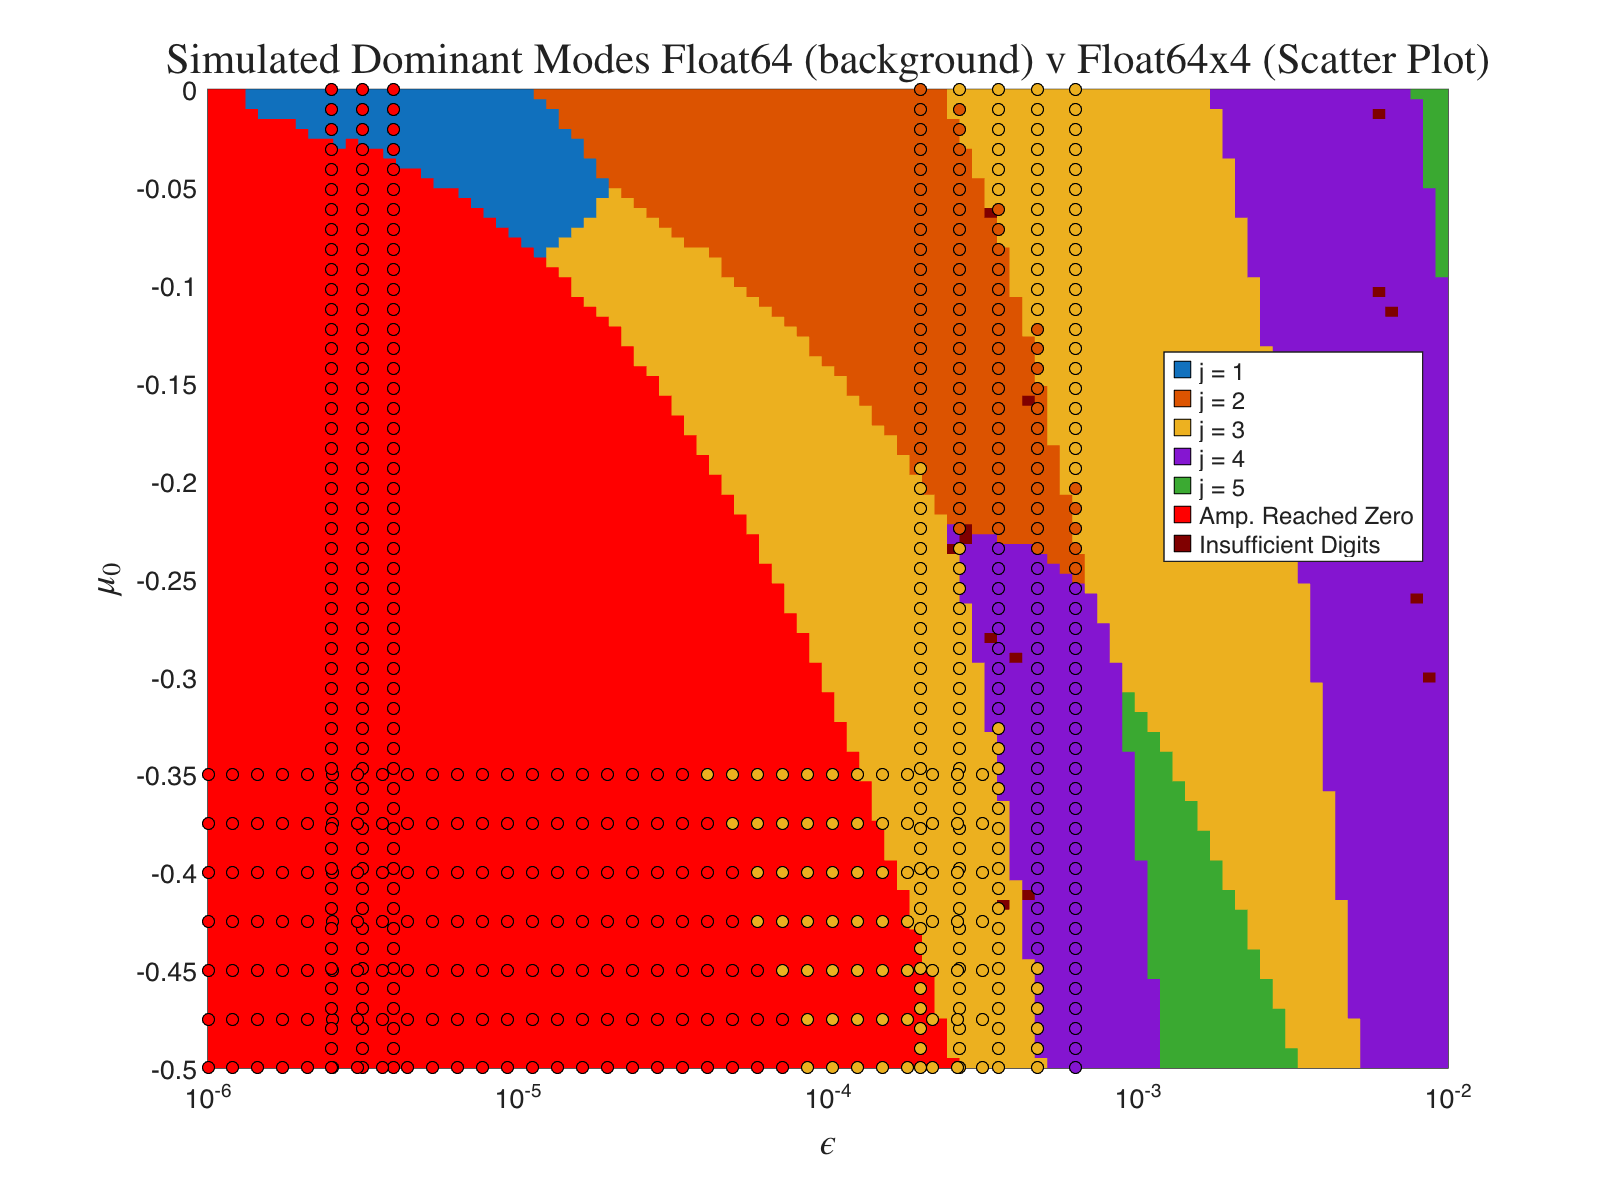

modified_mode_data = dmode_data;
modified_mode_data_64x4 = dmode_data_64x4;

% Define special identifiers for flags above the highest physical mode
max_physical_mode = max([dmode_data; dmode_data_64x4]); 
val_flag1 = max_physical_mode + 1; % Value representing Flag 1
val_flag2 = max_physical_mode + 2; % Value representing Flag 2

% Overwrite mode values where flags are triggered
modified_mode_data(flag_values == 1) = val_flag1;
modified_mode_data(flag_values == 2) = val_flag2;

modified_mode_data_64x4(flag_values_64x4 == 1) = val_flag1;
modified_mode_data_64x4(flag_values_64x4 == 2) = val_flag2;


%% Plot
figure('Position', [200 200 800 600], 'Resize', false);
hold on;

C_grid = griddata(Eps_data, Mu0_data, modified_mode_data, Eps_grid, Mu0_grid, 'nearest');
h = pcolor(Eps_grid, Mu0_grid, C_grid); 
shading flat; 
set(gca, 'XScale', 'log');

scatter(Eps_data_64x4, Mu0_data_64x4, 20, modified_mode_data_64x4, ...
    'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5, ...
    'MarkerFaceAlpha', 1.0, ... 
    'MarkerEdgeAlpha', 1.0);

% Colors
max_physical_mode = max(dmode_data);
base_colors = lines(max_physical_mode);
custom_colormap = [base_colors; ...
    1.0, 0.0, 0.0;   % Color for Flag 1 (Red)
    0.5, 0.0, 0.0];  % Color for Flag 2 (Dark Red)

colormap(custom_colormap);
clim([1, max_physical_mode + 2]);

% Formatting
set(gca, 'XScale', 'log');
xlim([1e-6, 1e-2]);
ylim([-0.5, 0]);

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_0$', 'Interpreter', 'latex', 'FontSize', 14);
title('Simulated Dominant Modes Float64 (background) v Float64x4 (Scatter Plot)', 'Interpreter', 'latex', 'FontSize', 16);

% Custom Legend for the regions
total_legend_items = max_physical_mode + 2;
p = gobjects(1, total_legend_items);
for i = 1:max_physical_mode
    p(i) = plot(NaN, NaN, 's', 'DisplayName', sprintf('j = %d', i), 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
end

% Add Flag 1 (Red) to legend
p(max_physical_mode + 1) = plot(NaN, NaN, 's', 'DisplayName', 'Amp. Reached Zero', ...
    'MarkerFaceColor', custom_colormap(val_flag1, :), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);

% Add Flag 2 (Dark Red) to legend
p(max_physical_mode + 2) = plot(NaN, NaN, 's', 'DisplayName', 'Insufficient Digits', ...
    'MarkerFaceColor', custom_colormap(val_flag2, :), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
legend(p, 'Location', 'best', 'Interpreter', 'tex');
hold off;
grid on;
box on;

## Plot simulated over approximated

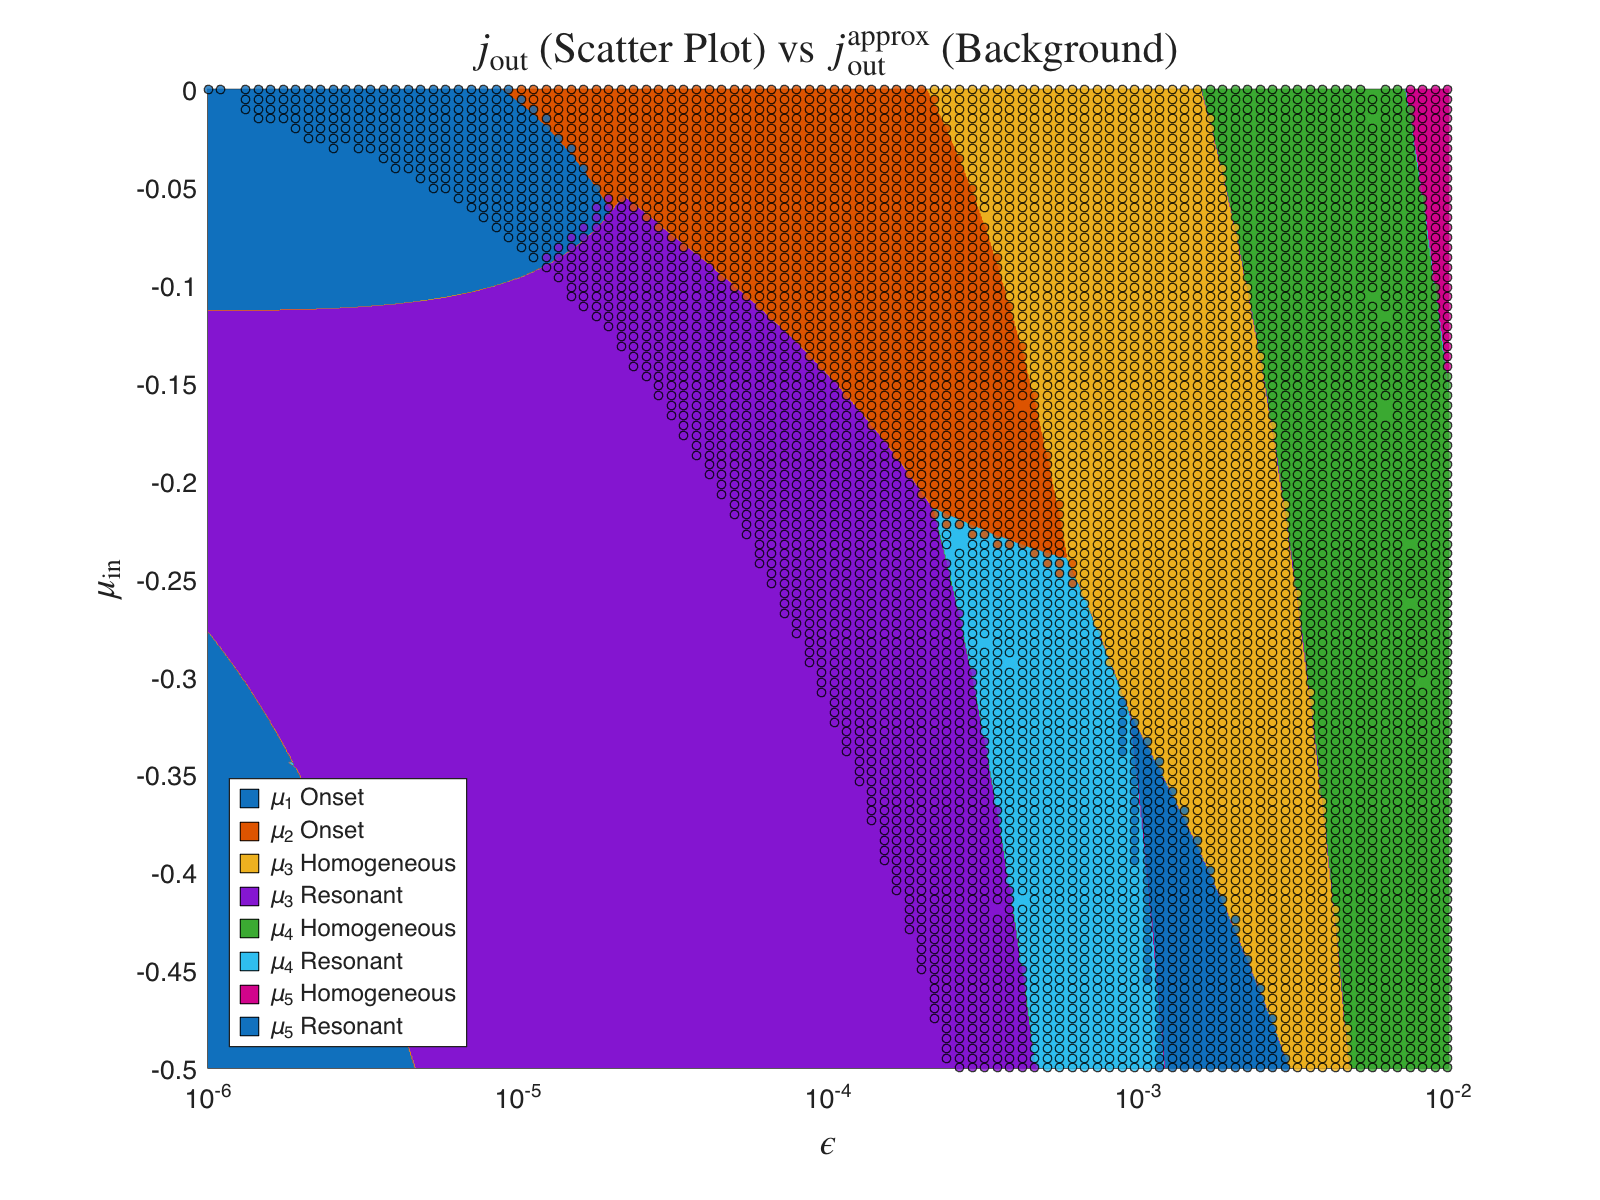

EPS = Eps_data(flag_values == 0);
MU0 = Mu0_data(flag_values == 0);

% Compute colors
c_valid = dmode_data(flag_values == 0);
c_mapped = c_valid;

% Move Mode 4 & 5 out of the way (will be split into 5 or 6 later)
c_mapped(c_valid == 5) = 7; 
c_mapped(c_valid == 4) = 5; 

% Shift Mode 6+ up to clear space for the split regimes
c_mapped(c_valid >= 6) = -1; 

% Disambiguate Mode 3 (Index 3 vs 4)
mode3_mask = (c_valid == 3);
if any(mode3_mask)
    % Extract coordinate subsets for evaluation
    eps_3 = EPS(mode3_mask);
    mu0_3 = MU0(mode3_mask);

    % Evaluate physical threshold onsets
    val_3_hom  = evaluate_real(mu3_hom_onset, eps_3, mu0_3);
    val_3_part = evaluate_real(mu3_res_onset, eps_3, mu0_3);

    idx_3 = find(mode3_mask);
    is_particular_3 = (val_3_part < val_3_hom);
    
    % Map the sub-indices back to c_mapped
    c_mapped(idx_3(is_particular_3))  = 4; % Particular regime
    c_mapped(idx_3(~is_particular_3)) = 3; % Homogeneous regime
end


% Disambiguate Mode 4 (Index 5 vs 6)
mode4_mask = (c_valid == 4);
if any(mode4_mask)
    % Extract coordinate subsets for evaluation
    eps_4 = EPS(mode4_mask);
    mu0_4 = MU0(mode4_mask);

    % Evaluate physical threshold onsets
    val_4_hom  = evaluate_real(mu4_hom_onset, eps_4, mu0_4);
    val_4_part = evaluate_real(mu4_res_onset, eps_4, mu0_4);

    % Sub-allocate based on which onset happens earlier
    is_particular_4 = (val_4_part < val_4_hom);
    idx_4 = find(mode4_mask);
    
    % Map the sub-indices back to c_mapped
    c_mapped(idx_4(is_particular_4))  = 6; % Particular regime
    c_mapped(idx_4(~is_particular_4)) = 5; % Homogeneous regime
end

% Disambiguate Mode 5 (Index 7 vs 8)
mode5_mask = (c_valid == 5);
if any(mode5_mask)
    % Extract coordinate subsets for evaluation
    eps_5 = EPS(mode5_mask);
    mu0_5 = MU0(mode5_mask);

    % Evaluate physical threshold onsets
    val_5_hom  = evaluate_real(mu5_hom_onset, eps_5, mu0_5);
    val_5_part = evaluate_real(mu5_res_onset, eps_5, mu0_5);

    % Sub-allocate based on which onset happens earlier
    is_particular_5 = (val_5_part < val_5_hom);
    idx_5 = find(mode5_mask);

    % Map the sub-indices back to c_mapped
    c_mapped(idx_5(is_particular_5))  = 8; % Particular regime
    c_mapped(idx_5(~is_particular_5)) = 7; % Homogeneous regime
end


% Plot
figure('Position', [200 200 800 600], 'Resize', false);
hold on;

% Plot the regions identifying which mode is the minimum
[~, h_reg] = contourf(Eps, Mu0, MinIdx_approx, [1 2 3 4 5 6 7 8], 'LineStyle', 'none');
alpha(0.3); 

scatter(EPS, MU0, 10, c_mapped, ...
    'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5, ...
    'MarkerFaceAlpha', 0.8, ... 
    'MarkerEdgeAlpha', 0.8);

% Color
max_mapped_color = max([8; c_mapped]); 
clim([1, max_mapped_color]); 
colors = colormap(lines(max_mapped_color));

% Formatting
set(gca, 'XScale', 'log');
xlim([1e-6, 1e-2]);
ylim([-0.5, 0]);

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_\mathrm{in}$', 'Interpreter', 'latex', 'FontSize', 14);
title('$j_\mathrm{out}$ (Scatter Plot) vs $j_\mathrm{out}^\mathrm{approx}$ (Background)', 'Interpreter', 'latex', 'FontSize', 16);

% Custom Legend for the regions
p = gobjects(1, length(8));
for i = 1:8
    p(i) = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
end

legend(p, {'\mu_1 Onset', '\mu_2 Onset', '\mu_3 Homogeneous', '\mu_3 Resonant', '\mu_4 Homogeneous', '\mu_4 Resonant', '\mu_5 Homogeneous', '\mu_5 Resonant'}, ...
    'Location', 'southwest', 'Interpreter', 'tex');
hold off;
grid on;
box on;

## Plot Float64x4 over approximate

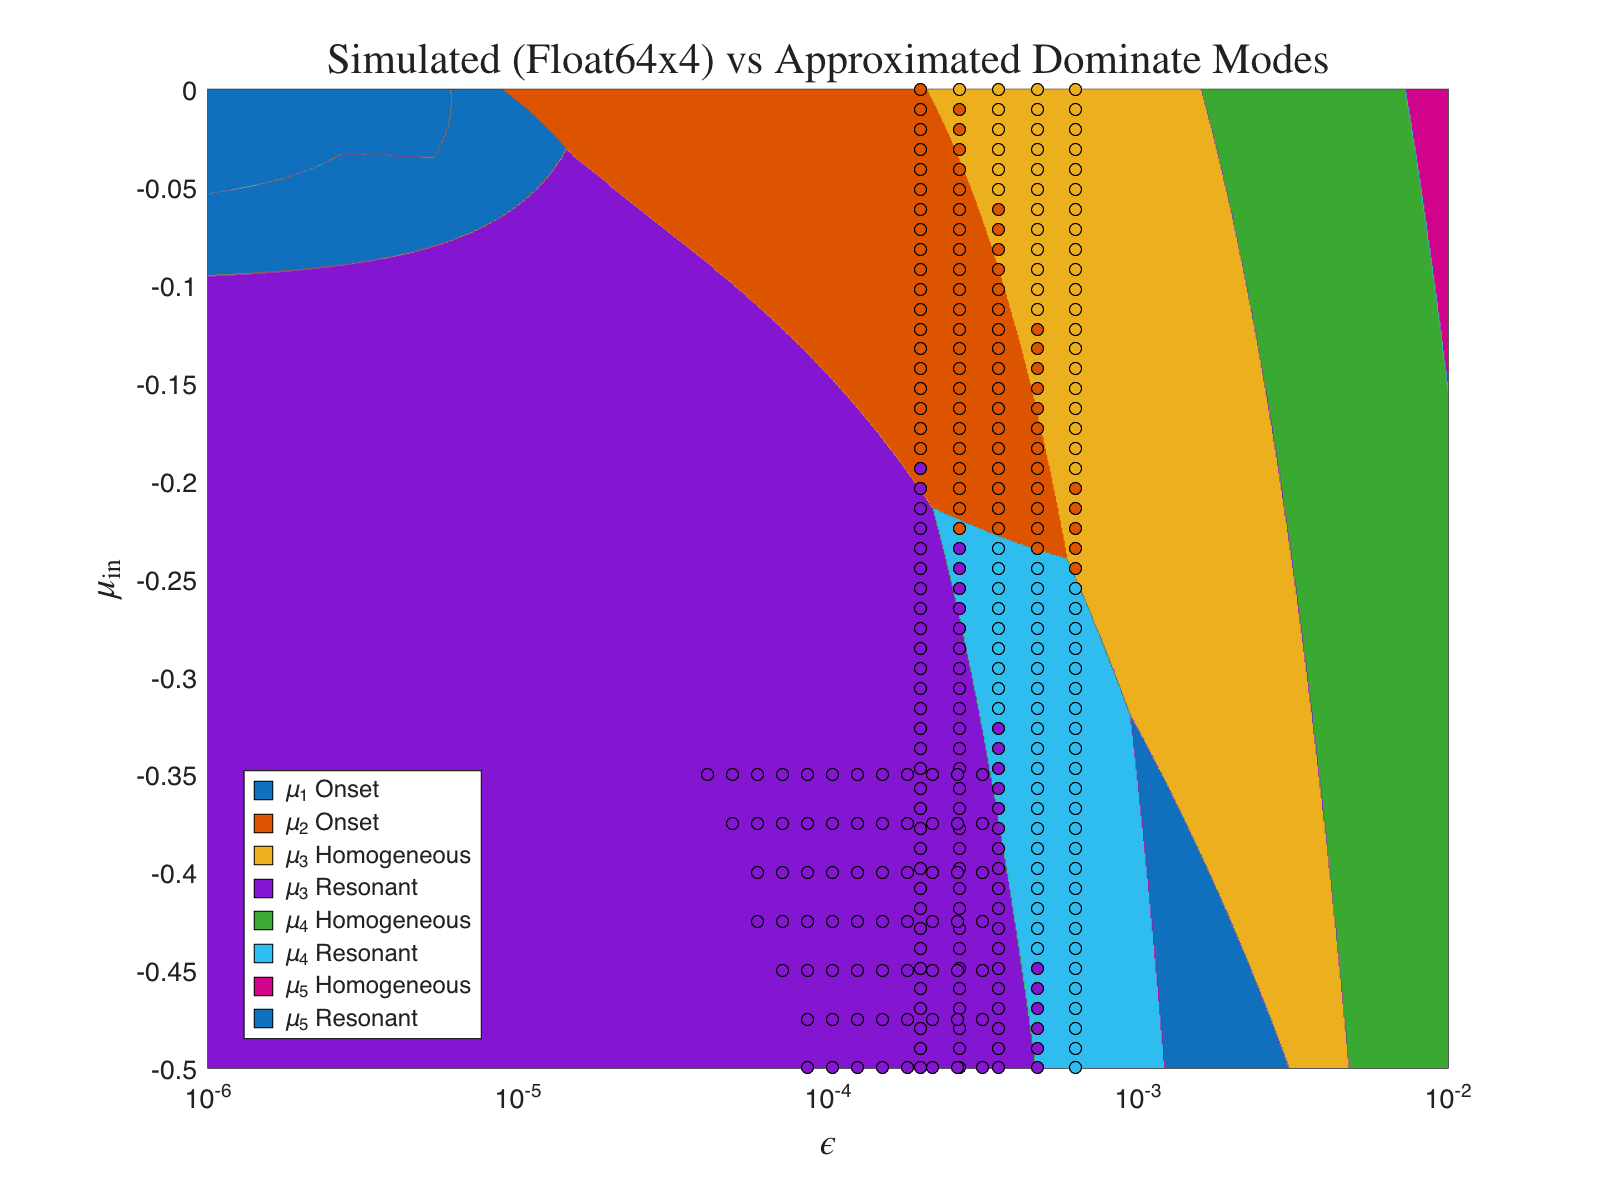

EPS = Eps_data_64x4(flag_values_64x4 == 0);
MU0 = Mu0_data_64x4(flag_values_64x4 == 0);

% Compute colors
c_valid = dmode_data_64x4(flag_values_64x4 == 0);
c_mapped = c_valid;


% Move Mode 4 & 5 out of the way (will be split into 5 or 6 later)
c_mapped(c_valid == 5) = 7; 
c_mapped(c_valid == 4) = 5; 

% Shift Mode 6+ up to clear space for the split regimes
c_mapped(c_valid >= 6) = -1; 

% Disambiguate Mode 3 (Index 3 vs 4)
mode3_mask = (c_valid == 3);
if any(mode3_mask)
    % Extract coordinate subsets for evaluation
    eps_3 = EPS(mode3_mask);
    mu0_3 = MU0(mode3_mask);

    % Evaluate physical threshold onsets
    val_3_hom  = evaluate_real(mu3_hom_onset, eps_3, mu0_3);
    val_3_part = evaluate_real(mu3_res_onset, eps_3, mu0_3);

    idx_3 = find(mode3_mask);
    is_particular_3 = (val_3_part < val_3_hom);

    % Map the sub-indices back to c_mapped
    c_mapped(idx_3(is_particular_3))  = 4; % Particular regime
    c_mapped(idx_3(~is_particular_3)) = 3; % Homogeneous regime
end


% Disambiguate Mode 4 (Index 5 vs 6)
mode4_mask = (c_valid == 4);
if any(mode4_mask)
    % Extract coordinate subsets for evaluation
    eps_4 = EPS(mode4_mask);
    mu0_4 = MU0(mode4_mask);

    % Evaluate physical threshold onsets
    val_4_hom  = evaluate_real(mu4_hom_onset, eps_4, mu0_4);
    val_4_part = evaluate_real(mu4_res_onset, eps_4, mu0_4);

    % Sub-allocate based on which onset happens earlier
    is_particular_4 = (val_4_part < val_4_hom);
    idx_4 = find(mode4_mask);

    % Map the sub-indices back to c_mapped
    c_mapped(idx_4(is_particular_4))  = 6; % Particular regime
    c_mapped(idx_4(~is_particular_4)) = 5; % Homogeneous regime
end

% Disambiguate Mode 5 (Index 7 vs 8)
mode5_mask = (c_valid == 5);
if any(mode5_mask)
    % Extract coordinate subsets for evaluation
    eps_5 = EPS(mode5_mask);
    mu0_5 = MU0(mode5_mask);

    % Evaluate physical threshold onsets
    val_5_hom  = evaluate_real(mu5_hom_onset, eps_5, mu0_5);
    val_5_part = evaluate_real(mu5_res_onset, eps_5, mu0_5);

    % Sub-allocate based on which onset happens earlier
    is_particular_5 = (val_5_part < val_5_hom);
    idx_5 = find(mode5_mask);

    % Map the sub-indices back to c_mapped
    c_mapped(idx_5(is_particular_5))  = 8; % Particular regime
    c_mapped(idx_5(~is_particular_5)) = 7; % Homogeneous regime
end

% Plot
figure('Position', [200 200 800 600], 'Resize', false);
hold on;

% Plot the regions identifying which mode is the minimum
[~, h_reg] = contourf(Eps, Mu0, MinIdx_pred, [1 2 3 4 5 6 7 8], 'LineStyle', 'none');
alpha(0.3); 

scatter(Eps_data_64x4(flag_values_64x4 == 0), Mu0_data_64x4(flag_values_64x4 == 0), 20, c_mapped, ...
    'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5, ...
    'MarkerFaceAlpha', 1.0, ... 
    'MarkerEdgeAlpha', 1.0);

% Color
max_mapped_color = max([8; c_mapped]); 
clim([1, max_mapped_color]); 
colors = colormap(lines(max_mapped_color));

% Formatting
set(gca, 'XScale', 'log');
xlim([1e-6, 1e-2]);
ylim([-0.5, 0]);

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_\mathrm{in}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Simulated (Float64x4) vs Approximated Dominate Modes', 'Interpreter', 'latex', 'FontSize', 16);

% Custom Legend for the regions
p = gobjects(1, length(8));
for i = 1:8
    p(i) = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
end

legend(p, {'\mu_1 Onset', '\mu_2 Onset', '\mu_3 Homogeneous', '\mu_3 Resonant', '\mu_4 Homogeneous', '\mu_4 Resonant', '\mu_5 Homogeneous', '\mu_5 Resonant'}, ...
    'Location', 'best', 'Interpreter', 'tex');
hold off;
grid on;
box on;

## Plot amplitudes over predicted amplitudes

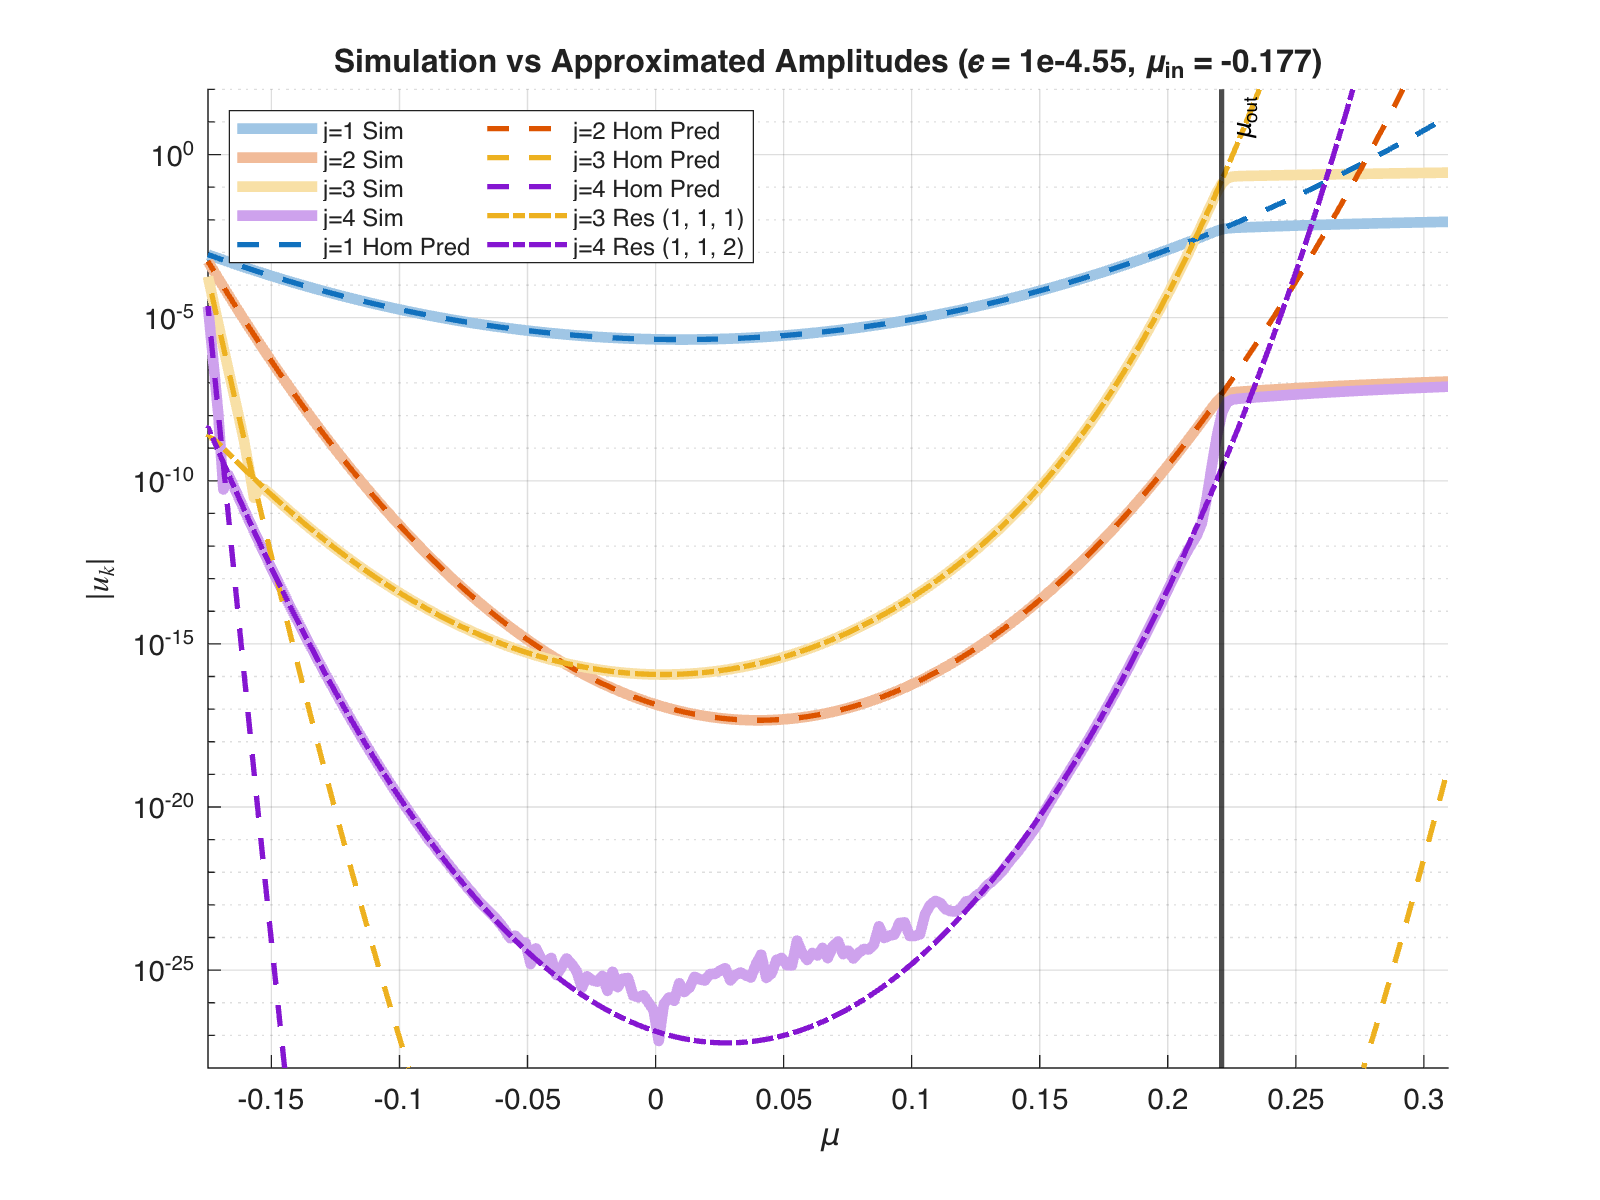

% Find index close for target eps and mu0
target_eps = 2.848e-5;
target_mu0 = -0.176716;

log_eps_data   = log10(Eps_data);
log_target_eps = log10(target_eps);

distances = sqrt((log_eps_data - log_target_eps).^2 + (Mu0_data - target_mu0).^2);
[~, idx] = min(distances);

ep = Eps_data(idx);
mu0 = Mu0_data(idx);

filename = sprintf('sample_ep=1e%.5f_mu0=%.7f_Float64.mat', log10(ep), mu0);

% Load data
data = load(filename);
t_grid = data.dt * (0:length(data.L2_HIST)-1)';
mu_grid = t_grid * ep + mu0;
amp_hists = data.AMP_HISTS;

clear data

% Crop data
idxs = 1:100:length(mu_grid);
mu_grid = mu_grid(idxs);
amp_hists = amp_hists(:, idxs);

% Plot data
figure('Position', [200 200 800 600], 'Resize', true);
hold on;

colors = lines(5); 
legend_entries = {};

% Plot Full PDE Data (Thick, lighter lines)
for k = 1:4
    light_color = colors(k, :) + (1 - colors(k, :)) * 0.6;
    plot(mu_grid, amp_hists(k, :), '-', 'Color', light_color, 'LineWidth', 4);
    legend_entries{end+1} = sprintf('j=%d Sim', k);
end

% Plot Homogenous Data (Dashed lines)
log_uk_hom = @(mu, mu0, eps, k) log(delta) + (Lambdak(mu, k) - Lambdak(mu0, k)) / eps;
for k = 1:4
    log_hom = log_uk_hom(mu_grid, mu0, ep, k);
    plot(mu_grid, exp(log_hom), '--', 'Color', colors(k, :), 'LineWidth', 2);
    legend_entries{end+1} = sprintf('j=%d Hom Pred', k);
end
 
%% Plot Resonant Data (Dashed Dotted lines)
plot(mu_grid, exp(log_u3_res(mu_grid, mu0, ep)), '-.', 'Color', colors(3, :), 'LineWidth', 2)
legend_entries{end+1} = 'j=3 Res (1, 1, 1)';

plot(mu_grid, exp(log_u4_res(mu_grid, mu0, ep)), '-.', 'Color', colors(4, :), 'LineWidth', 2)
legend_entries{end+1} = 'j=4 Res (1, 1, 2)';

% plot(mu_grid, exp(log_u5_res(mu_grid, mu0, ep)), '-.', 'Color', colors(5, :), 'LineWidth', 2)
% legend_entries{end+1} = 'j=5 Res (1, 2, 2)';

hold off;

xline(mu_out_data(idx), '-', 'Color', 'k', 'LineWidth', 2, 'Label', '\mu_{out}');

xlabel('\mu', 'FontSize', 12);
ylabel('$|u_k|$', 'FontSize', 12, 'Interpreter', 'latex');
title(sprintf('Simulation vs Approximated Amplitudes (\\epsilon = 1e%.2f, \\mu_{in} = %0.3f)', log10(ep), mu0), 'FontSize', 14);

legend(legend_entries, 'Location', 'northwest', 'FontSize', 9, 'NumColumns', 2);
xlim([mu_grid(2), mu_out_data(idx) * 1.4])
ylim([1e-28, 1e2])
yscale log
grid on;
hold off;
set(gca, 'FontSize', 11);

## Plot residuals of mu0_out in valid region

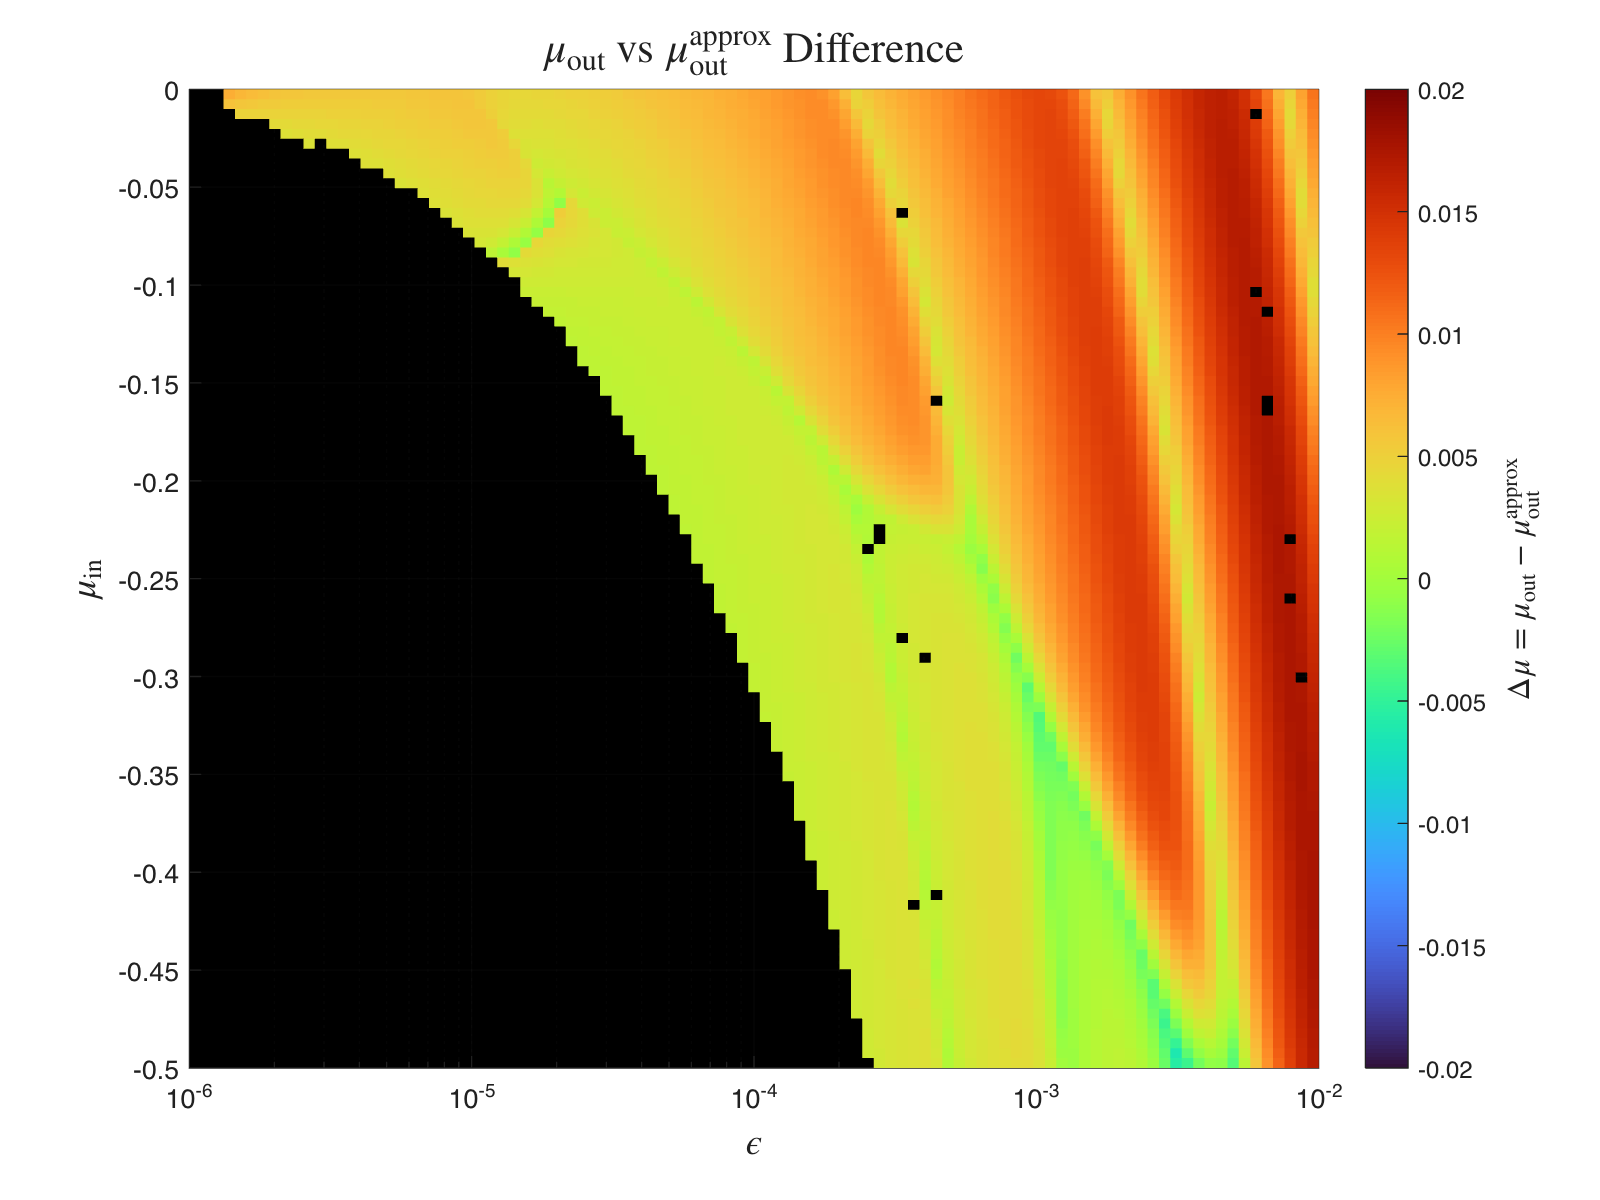

eps_coarse = unique(Eps_data(:));
mu0_coarse = unique(Mu0_data(:));
[Eps_coarse, Mu0_coarse] = meshgrid(eps_coarse, mu0_coarse);

mu_out_coarse = griddata(Eps_data(:), Mu0_data(:), mu_out_data(:), Eps_coarse, Mu0_coarse, 'nearest');
flag_coarse   = griddata(Eps_data(:), Mu0_data(:), double(flag_values(:)), Eps_coarse, Mu0_coarse, 'nearest');
flagged_mask = flag_coarse ~= 0;

% Lower the resolution of the analytical MinSurface to match the coarse
% grid (it is exact as its grid is a refinement of the coarse grid)
MinSurface_coarse = interp2(Eps, Mu0, MU_approx, Eps_coarse, Mu0_coarse, 'nearest');

DiffSurface = mu_out_coarse - MinSurface_coarse;
DiffSurface(flagged_mask) = NaN;

% --- PLOTTING ---
figure('Position', [200 200 800 600], 'Resize', false);
ax = gca;
ax.Color = 'k'; % Black axes background makes NaN regions appear blacked out
hold on;

% Plot the filled contour differences
h = pcolor(Eps_grid, Mu0_grid, DiffSurface); 
shading flat; 
set(gca, 'XScale', 'log');

% Color mapping and Colorbar
colormap(turbo); % 'turbo' or 'parula' 
cb = colorbar;
ylabel(cb, "$\Delta\mu =\mu_{\mathrm{out}} - \mu_{\mathrm{out}}^{\mathrm{approx}}$", 'FontSize', 12, 'Interpreter', 'latex');

% Formatting
xlim([min(eps_coarse), max(eps_coarse)]);
ylim([min(mu0_coarse), max(mu0_coarse)]);

clim([-0.02, 0.02])

xlabel('$\epsilon$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\mu_\mathrm{in}$', 'Interpreter', 'latex', 'FontSize', 14);
title("$\mu_\mathrm{out}$ vs $\mu_\mathrm{out}^\mathrm{approx}$ Difference", 'Interpreter', 'latex', 'FontSize', 16);

grid on;
box on;
hold off;

## Plot Cross-sections

col = 60;
eps = eps_coarse(col);
mu0_grid_sim = mu0_coarse;
mu_out_sim = mu_out_coarse(:, col);

[~, col_dense] = min(abs(eps_vec - eps)); 
mu0_grid_approximate = Mu0(:, col_dense);
mu_out_approximate = MU_approx(:, col_dense);


fprintf('Taking a slice of eps=1e%.4f', log10(eps));

Taking a slice of eps=1e-3.6162

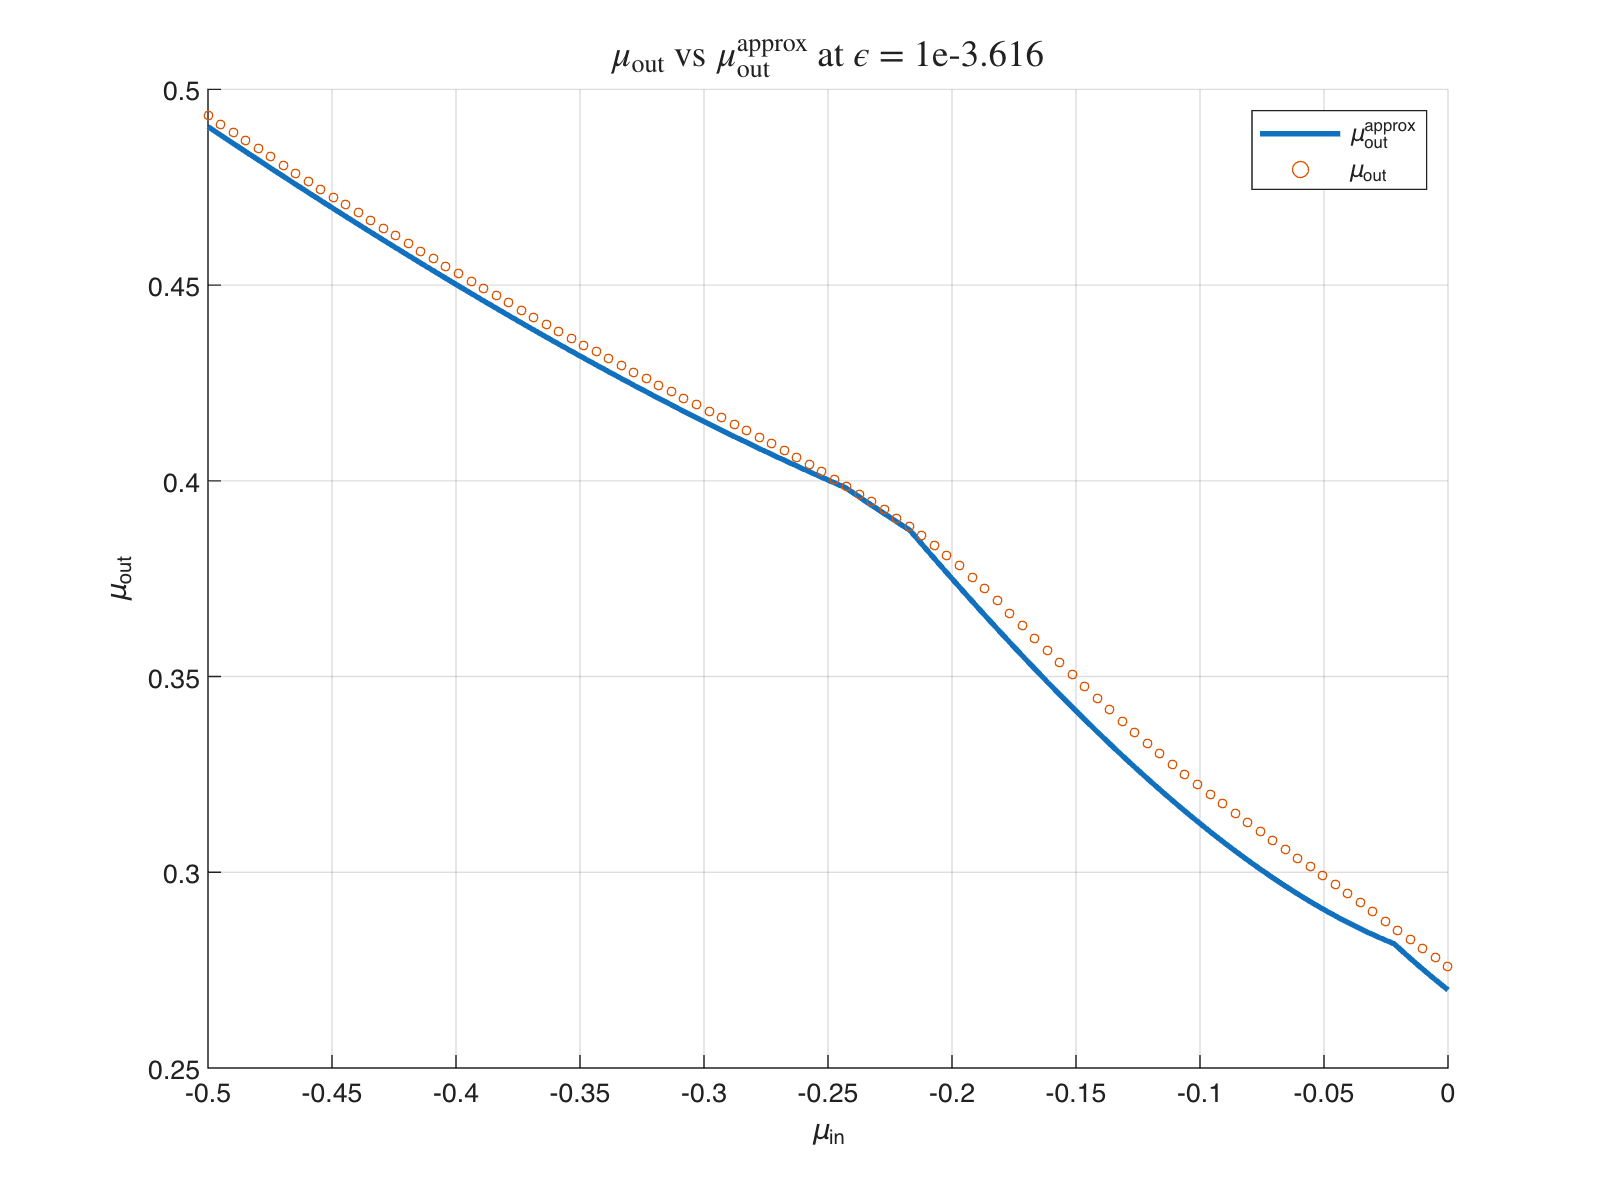


figure('Position', [200 200 800 600], 'Resize', true);
hold on;

plot(mu0_grid_approximate, mu_out_approximate,'LineWidth', 2, 'DisplayName', "\mu^{approx}_{out}");
scatter(mu0_grid_sim, mu_out_sim, 10,'DisplayName', "\mu_{out}");

title(sprintf("$\\mu_\\mathrm{out}$ vs $\\mu_\\mathrm{out}^\\mathrm{approx}$ at $\\epsilon$ = 1e%.3f", log10(eps)), 'Interpreter', 'latex', 'FontSize', 14)
xlabel('\mu_{in}')
ylabel('\mu_{out}')

legend;
hold off; 
grid on;

## Asch paper

Solving b1(mu) = 0

mu_out_b1 =  @(mu0) ktilde2(1) + sqrt(ktilde2(1)^2 + 2 / ktilde2(1) .* ...
    Lambdak(mu0, 1));

% mu for when lambda3 = 3 * lambda1
mu_13_res = 13 * ktilde2(1);

% Solving b3(mu) = 0 (Fixed Lambdak(mu_13_res, 3))
mu_out_b3_res = @(mu0) ktilde2(3) + sqrt(ktilde2(3)^2 + 2 / ktilde2(3) .* ...
    (Lambdak(mu_13_res, 3) - 3 * Lambdak(mu_13_res, 1) + 3 * Lambdak(mu0, 1)));

## PLOT 2: Plot the Asch condition as a function of mu0

figure('Position', [200 200 800 600], 'Resize', true); hold on;

plot(mu0_vec, mu_out_b1(mu0_vec), 'Color', colors(1,:), 'DisplayName', 'b_1');

b3_res = mu_out_b3_res(mu0_vec); after_res = b3_res > mu_13_res; plot(mu0_vec(after_res), b3_res(after_res), 'Color', colors(4,:), 'DisplayName', 'b_{3, res}');

yline(mu_13_res, '--', 'Color', colors(4,:), 'DisplayName', '\mu_{1^3:3}', 'Interpreter', 'tex')

title('Asch Paper Algorithm') xlabel('\mu_0') ylabel('\mu_{out}')

legend('Location', 'best'); grid on; hold off;

% --- HELPER FUNCTION ---
function Z = evaluate_real(func, X, Y)
    % Evaluates the function and masks imaginary results as NaN
    % This prevents invalid onset times from affecting the minimum calculation
    Z = func(X, Y);
    imag_mask = imag(Z) ~= 0;
    Z(imag_mask) = NaN;
    Z = real(Z);
end

function val = log_abs_erf_diff(x, y)
    % Vectorized, high-precision evaluation of log(abs(erf(x) - erf(y)))
    % Prevents underflow/overflow/saturation at extreme scales via erfcx.
    
    % Ensure X >= Y element-wise to exploit mathematical identities safely
    X = max(x, y);
    Y = min(x, y);
    
    val = zeros(size(X));
    safe_log = @(v) log(max(v, 1e-300)); % Protects against strict log(0)
    
    % Case 1: Both coordinates are positive (X >= Y >= 0)
    maskA = (Y >= 0);
    if any(maskA)
        XA = X(maskA); YA = Y(maskA);
        val(maskA) = -YA.^2 + safe_log(erfcx(YA) - erfcx(XA) .* exp(YA.^2 - XA.^2));
    end
    
    % Case 2: Both coordinates are negative (0 >= X >= Y)
    maskB = (X <= 0);
    if any(maskB)
        XB = X(maskB); YB = Y(maskB);
        val(maskB) = -XB.^2 + safe_log(erfcx(-XB) - erfcx(-YB) .* exp(XB.^2 - YB.^2));
    end
    
    % Case 3: Coordinates have different signs (Y < 0 < X)
    % No dangerous boundary layer subtractions occur here; direct sum is stable.
    maskC = (Y < 0 & X > 0);
    if any(maskC)
        XC = X(maskC); YC = Y(maskC);
        val(maskC) = safe_log(erf(XC) + erf(-YC));
    end
end